Consider the confound of scanner manufacture.

scanner: similarity of scanner manufacture between sites

BD


                      scanner 
                     _________

    spearman corr    -0.095244
    p                  0.27961



SCA


                     scanner 
                     ________

    spearman corr    0.076579
    p                 0.28327



SCZ


                      scanner 
                     _________

    spearman corr    -0.028185
    p                  0.43093



ASD


                      scanner 
                     _________

    spearman corr    -0.087039
    p                  0.26344



MDD


                     scanner 
                     ________

    spearman corr    0.033134
    p                 0.42073



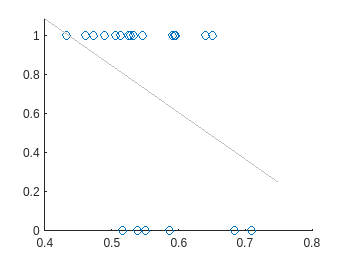

AD


                     scanner 
                     ________

    spearman corr    -0.34816
    p                 0.19759



% Clear workspace and close all figures
clear all
close all

% Define parameters
iCOMBAT = 1; % Flag for applying COMBAT harmonization
smoothKernel = 10; % Smoothing kernel size
iter = 5000; % Number of iterations for Mantel test
hemi = 'lh'; % Hemisphere (e.g., left hemisphere)
type = 'spearman'; % Type of correlation (Spearman rank correlation)
diagnosisString = {'BD', 'SCA', 'SCZ', 'ASD', 'MDD', 'AD'}; % List of diagnoses

nDiag = length(diagnosisString); % Number of diagnoses

% Set the address path based on whether COMBAT is applied
if iCOMBAT == 1
    address = ['derivatives/s', num2str(smoothKernel), 'COMBAT/'];
else
    address = ['derivatives/s', num2str(smoothKernel), '/'];
end
% Load metadata (scanner information)
metadata = readtable(['/home/trangc/kg98/trangc/VBM/data/scanner_site_detailed.csv'], 'VariableNamingRule', 'preserve');

% Load precomputed correlation matrices and site information
load(['output/corr_zmap_combat', num2str(iCOMBAT), '_smooth', num2str(smoothKernel), '_', hemi, '_all.mat'], ...
    'map', 'corDiag',  'siteList');

% Initialize variables for results
varTable = cell(nDiag, 1);
nSite = cell(nDiag, 1);

% Loop through each diagnosis
for iDiag = 1:nDiag
    % Compute variance related to scanner manufacturer similarity between sites
    [varTable{iDiag} scannerSim{iDiag} nSite{iDiag}] = cor_var_scanner(metadata,  diagnosisString(iDiag), corDiag{iDiag}, siteList{iDiag}, iter, type);
       % Display results for the current diagnosis
    if size(varTable,1)~=0
        disp(char(diagnosisString(iDiag)))
        disp(varTable{iDiag})
        disp(' ')
        disp(' ')
    end
end


% Suppress warnings related to the last operation
warning('off','last')

Error using warning
The last warning issued had an empty warning identifier, or no warnings have yet been issued.

save('output/confound_scanner.mat','varTable','scannerSim','nSite')